clear all;close all;

% mo=load(['C:\Users\sgrc-325\Desktop\git\others\acc_logger\0327_11.csv']);

mo1=load(['C:\Users\sgrc-325\Desktop\git\others\acc_logger\data\0402_1.csv']);
mo2=load(['C:\Users\sgrc-325\Desktop\git\others\acc_logger\data\0403_0.csv']);
mo3=load(['C:\Users\sgrc-325\Desktop\git\others\acc_logger\data\0404_33.csv']);
mo4=load(['C:\Users\sgrc-325\Desktop\git\others\acc_logger\data\0405_0.csv']);
mo=[mo1;mo2;mo3;mo4];
mo(1:100,:)=[];


[N,~]=size(mo);

[a1 a2]=size(mo);
t=mo(:,1);
acc1 = mo(:,3:5);  %無校正
temp=mo(:,6);
ax1=acc1(:,1);ay1=acc1(:,2);az1=acc1(:,3);

% 計算俯仰角 (Pitch) 和橫滾角 (Roll)
pitch = atan(ay1 ./ sqrt(ax1.^2 + az1.^2)) * (180 / pi);
roll = atan(-ax1 ./ az1) * (180 / pi);

std(acc1)' %看標準差

ans =     0.0040
    0.0033
    0.0085


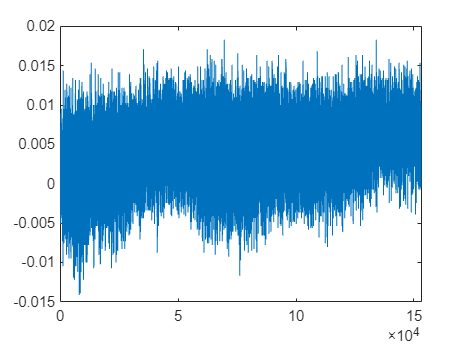

close all;
figure(1)
plot(t,ax1)

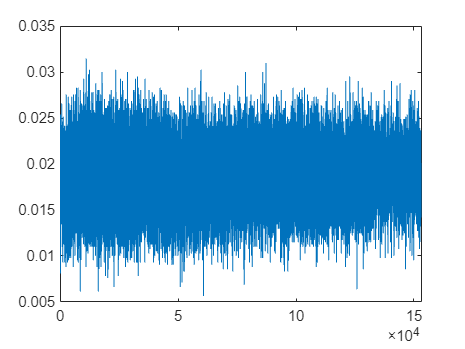

figure(2)
plot(t,ay1)

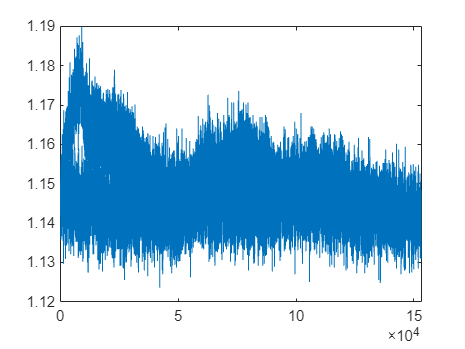

figure(3)
plot(t,az1)

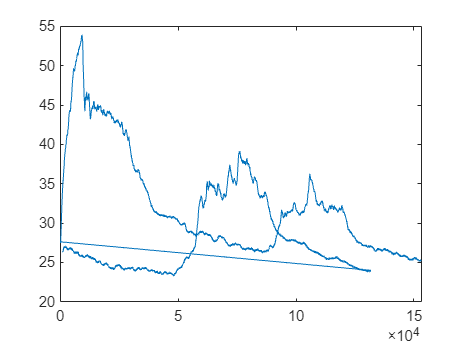


figure(4)
plot(t,temp)

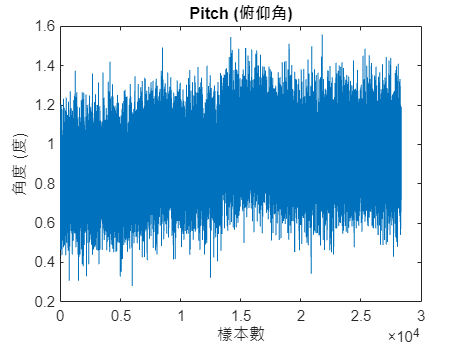

close all;
figure(1)
plot(pitch);
title('Pitch (俯仰角)');
xlabel('樣本數');
ylabel('角度 (度)');

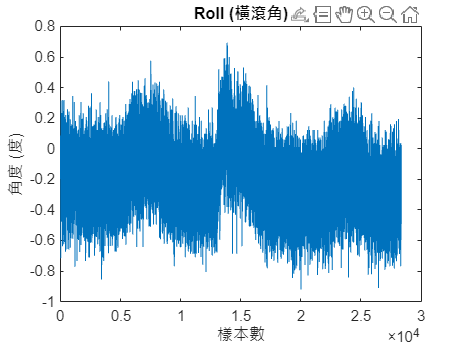


figure(2)
plot(roll);
title('Roll (橫滾角)');
xlabel('樣本數');
ylabel('角度 (度)');

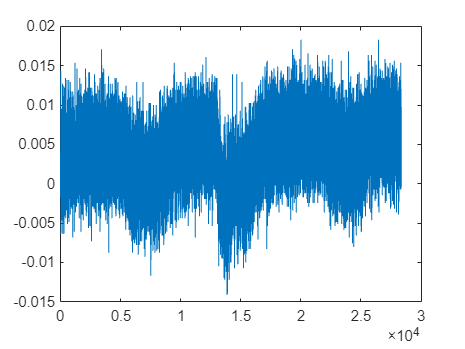

close all;
figure(1)
plot(ax1)

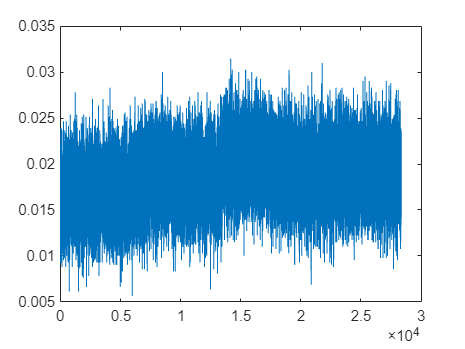

figure(2)
plot(ay1)

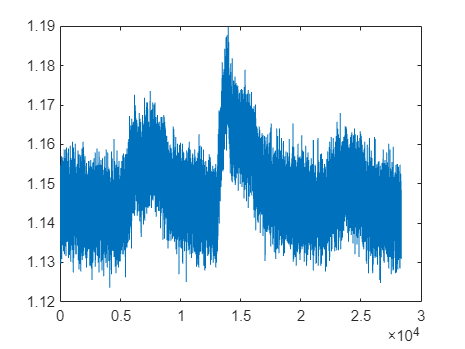

figure(3)
plot(az1)

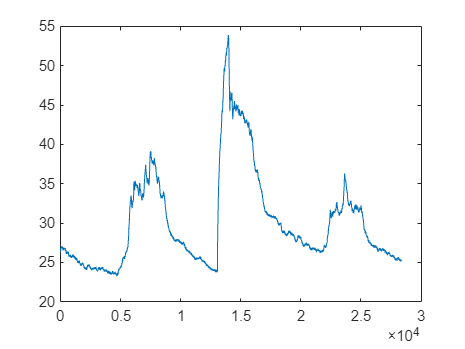


figure(4)
plot(temp)

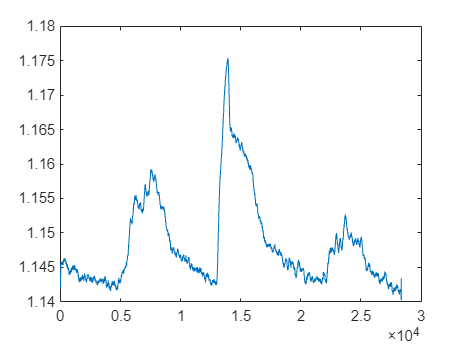


figure(7)
plot(smooth(az1,150))

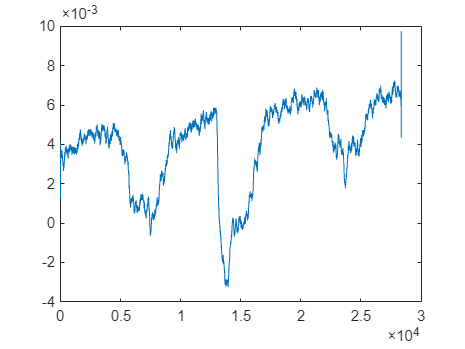

figure(5)
plot(smooth(ax1,150))

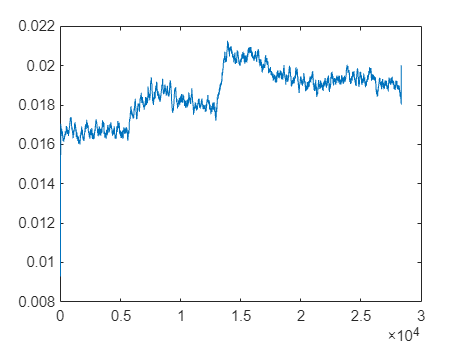

figure(6)
plot(smooth(ay1,150))